# Sampling Rate Conversion

#### Signal

Get Sound signal: 

clc;
close all;
clear all;
%load path
path(path,'C:\Users\rdegi\Desktop\HS21\DSVB\Multirate Signal Processing and Filter Banks');

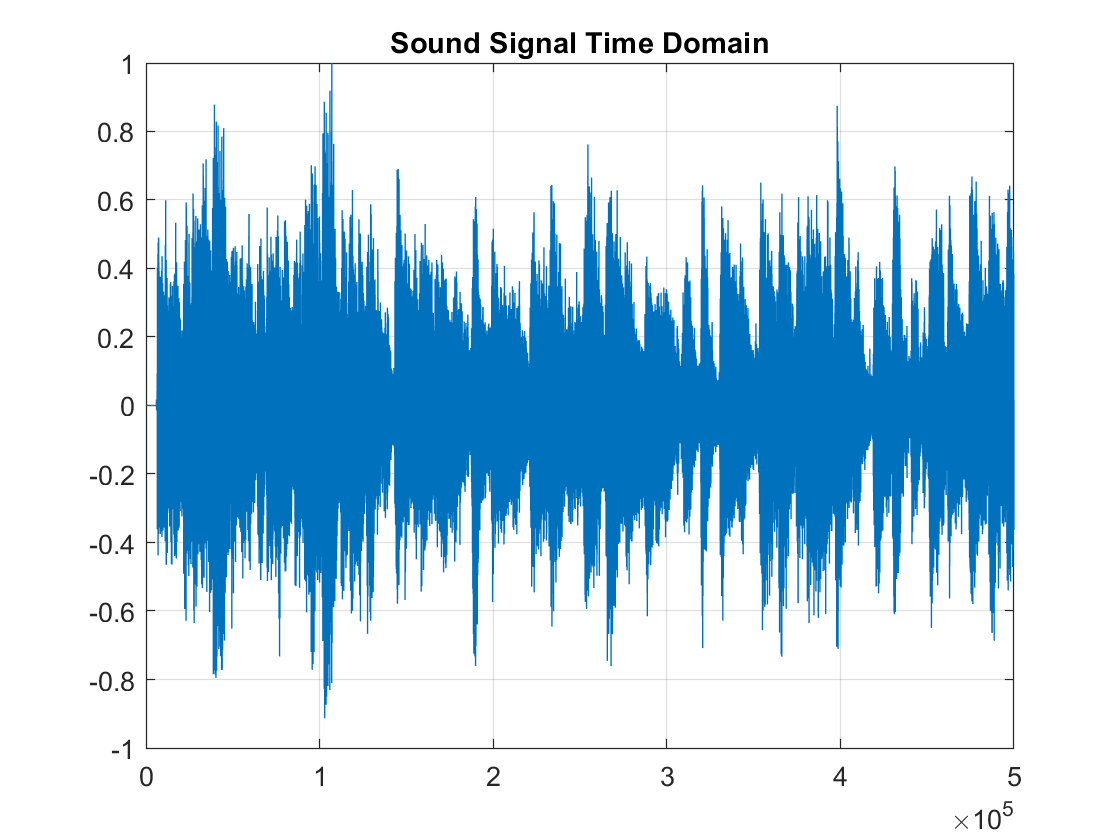


X = audioread('music1.wav');
p = X(1:500000,1)'/max(abs(X(1:500000,1)));%why 500 000
% sound(p,44100);
figure;
plot(p)
title('Sound Signal Time Domain')
grid on;

Display Frequency Spectrum

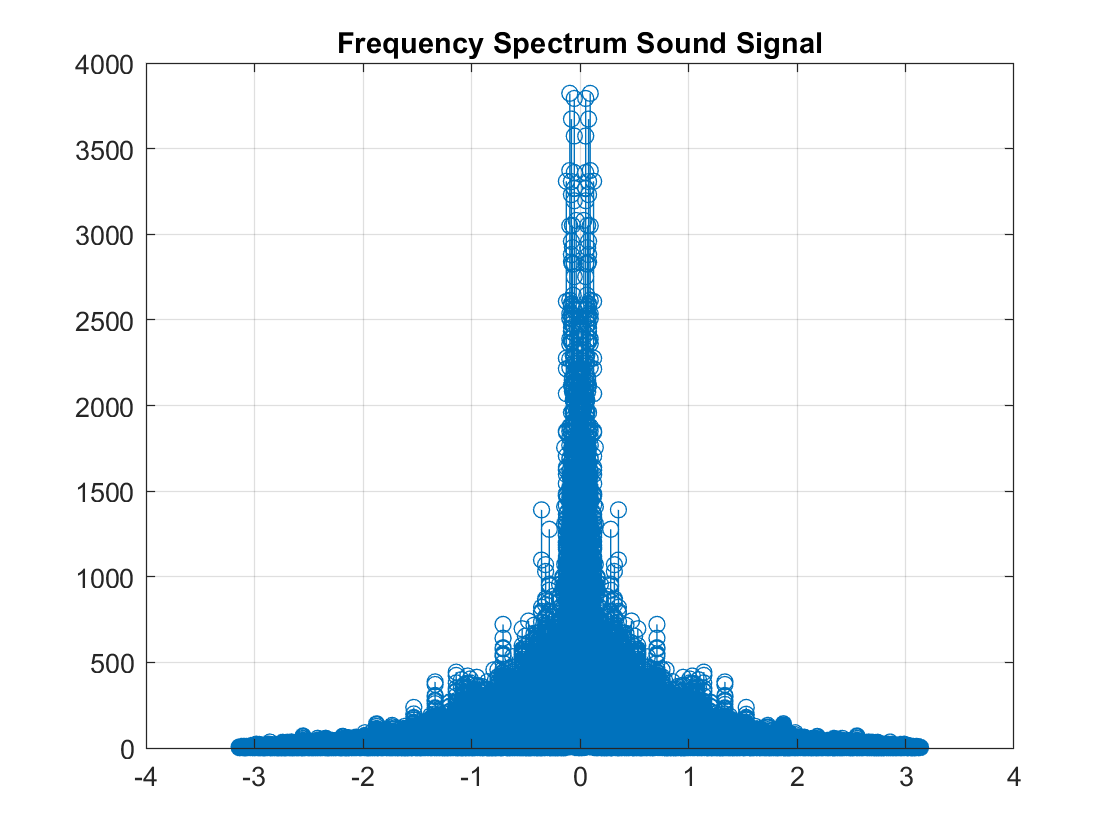

interval=[-pi:(2*pi)/(length(p)):pi-(2*pi)/length(p)];
figure;
stem(interval,fftshift(abs(fft(p))))
axis([-4 4 0 4000])
grid on;
title('Frequency Spectrum Sound Signal')

## Upsampling 

#### Theory:

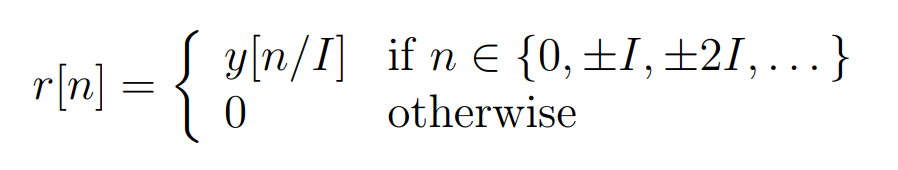

if I=2 set r[...-6,-4,-2,0,2,4,6...] = y[n] otherwise 0

y_n=[1 1 1 1]

y_n =      1     1     1     1


I=2;
r_n=[1 0 1 0 1 0 1 0]

r_n =      1     0     1     0     1     0     1     0


%compare to built in matlab function:
y=upsample(y_n,2)

y =      1     0     1     0     1     0     1     0


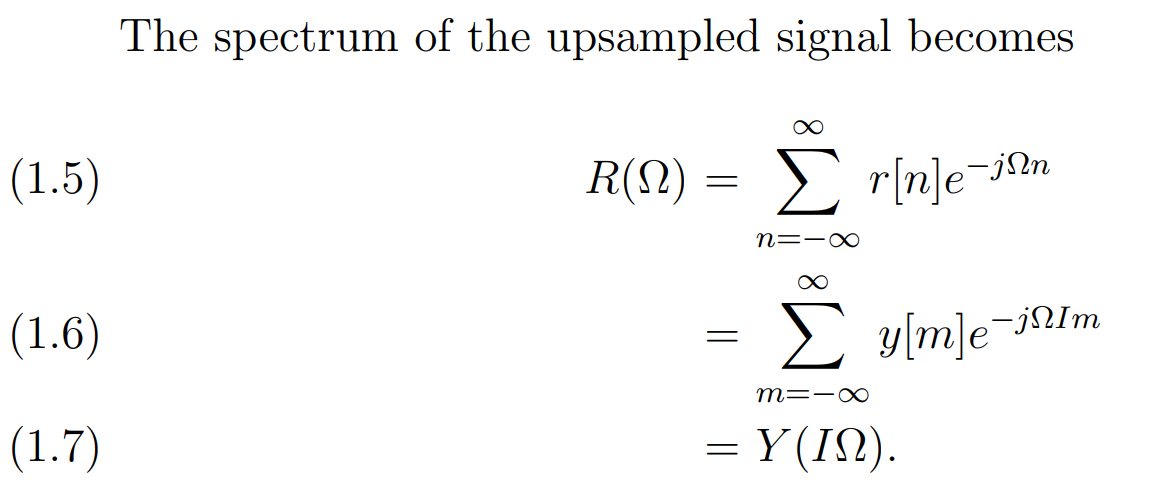

your fastest frequency will go around the unitcircle once. This is how it is defined. If you multiply all your frequencies by I, the fastest frequency will be I times faster. Meaning, that the frequency which was fastest before will be at the angle 2pi/I not 2pi.

I=2.7

I = 2.7000

n=[0:0.1/(2*I):2*pi]

n =          0    0.0185    0.0370    0.0556    0.0741    0.0926    0.1111    0.1296    0.1481    0.1667    0.1852    0.2037    0.2222    0.2407    0.2593    0.2778    0.2963    0.3148    0.3333    0.3519    0.3704    0.3889    0.4074    0.4259    0.4444    0.4630    0.4815    0.5000    0.5185    0.5370    0.5556    0.5741    0.5926    0.6111    0.6296    0.6481    0.6667    0.6852    0.7037    0.7222    0.7407    0.7593    0.7778    0.7963    0.8148    0.8333    0.8519    0.8704    0.8889    0.9074


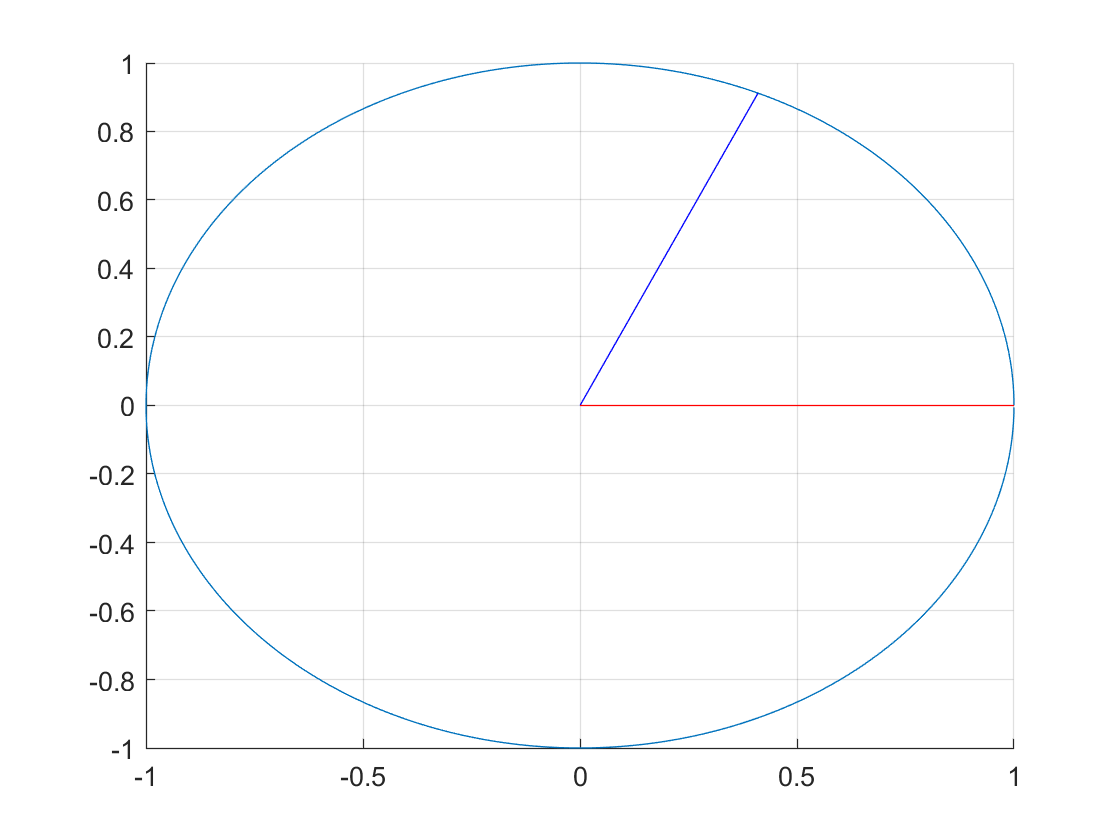

fastest_old=exp(1j*n(63));
secondfastest_old=exp((1j*n(1)));
figure;
grid on;
hold on;
plot(real(exp(1j*n)),imag(exp(1j*n)))
line([0 real(fastest_old)],[0 imag(fastest_old)],'Color','blue');
line([0 real(secondfastest_old)],[0 imag(secondfastest_old)],'Color','red');
hold off;

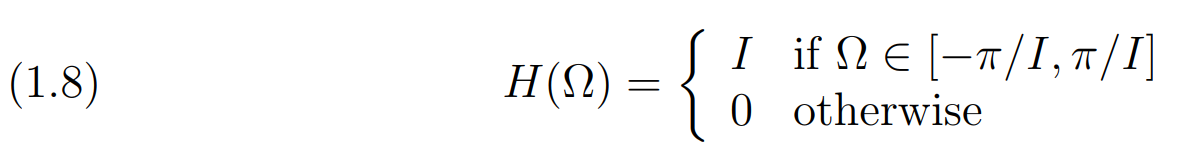

Since all of our frequencyspectra are periodic and upsampling means a compression of the spectrum in the baseband by I, it means that periodic ferquency components will be shiftet to the baseband. In order to filter these out, it is necessary to apply a LP-Filter

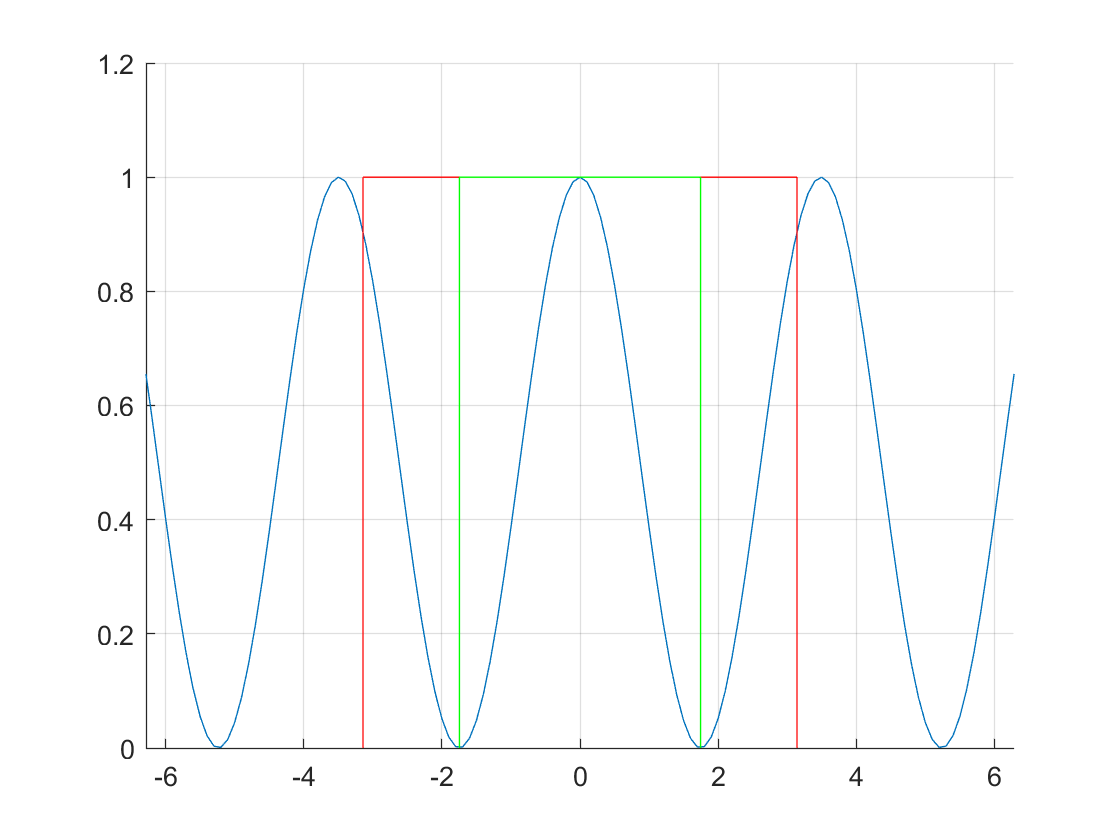

I=1.8;
f=[-10:0.1:10];
figure;
grid on;
hold on;
plot(f,0.5*cos(I*f)+0.5)
line([-pi pi],[1 1],'Color','red')
line([-pi -pi],[1 0],'Color','red')
line([pi pi],[1 0],'Color','red')
line([-pi/I pi/I],[1 1],'Color','green')
line([-pi/I -pi/I],[1 0],'Color','green')
line([pi/I pi/I],[1 0],'Color','green')
axis([-2*pi 2*pi 0 1.2])

The Green line shows, at which frequency one has to choos the cut-off frequency for the lowpassfilter

in order to prevent aliasing.

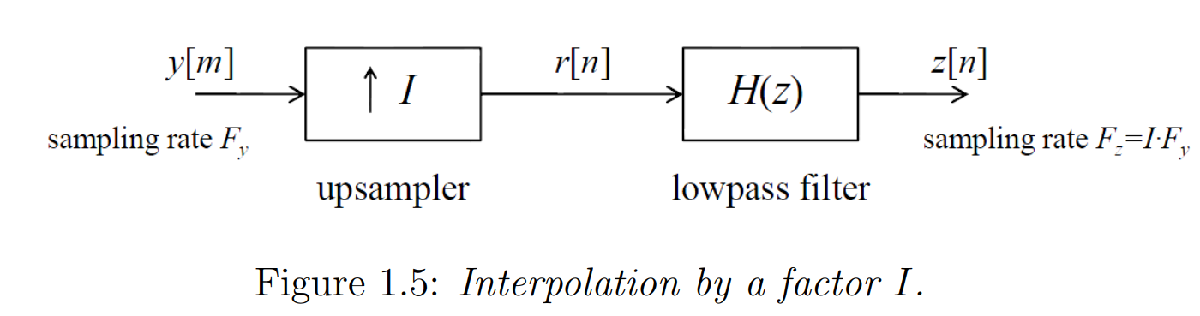

Another Example:

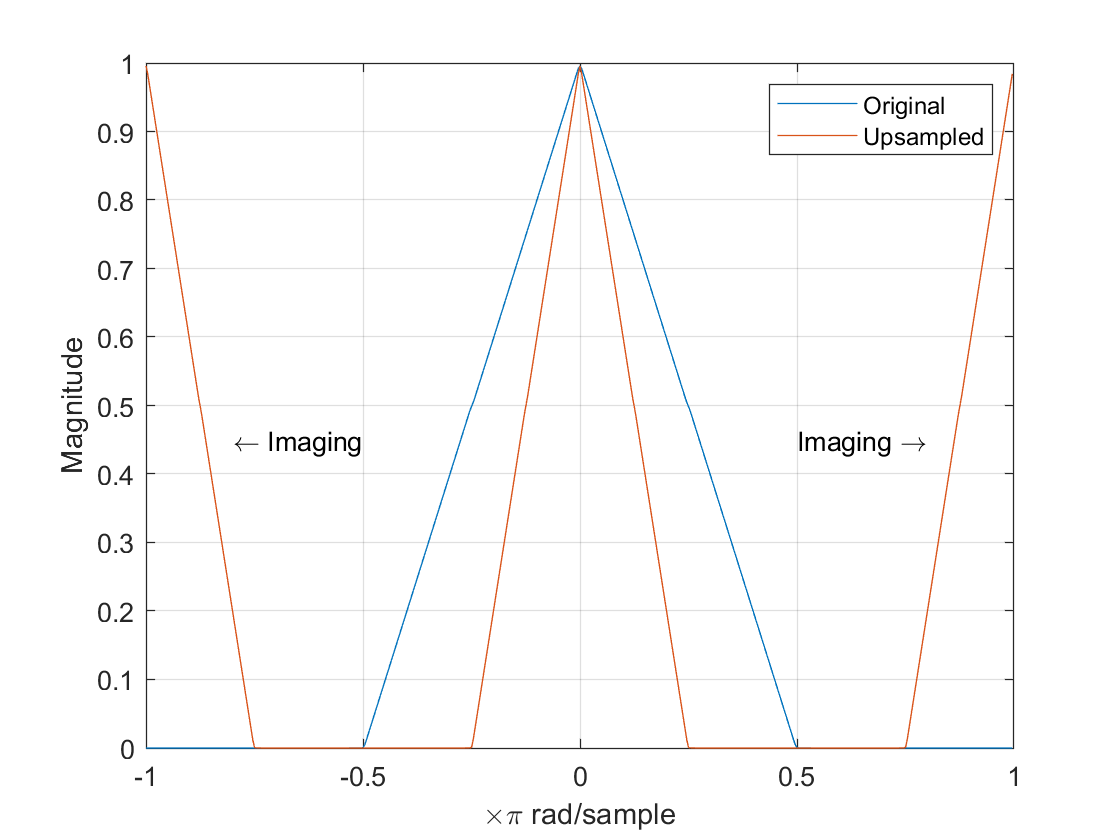

%source of this section: https://ch.mathworks.com/help/signal/ug/upsampling-imaging-artifacts.html?searchHighlight=upsample&s_tid=srchtitle_upsample_4
f = [0 0.250 0.500 0.7500 1];
a = [1.0000 0.5000 0 0 0];

nf = 512;
b = fir2(nf-1,f,a);
Hx = fftshift(freqz(b,1,nf,'whole'));

omega = -pi:2*pi/nf:pi-2*pi/nf;
figure;
plot(omega/pi,abs(Hx))
grid
xlabel('\times\pi rad/sample')
ylabel('Magnitude')
y = upsample(b,2);
Hy = fftshift(freqz(y,1,nf,'whole'));

hold on
plot(omega/pi,abs(Hy))
hold off
legend('Original','Upsampled')
text(0.65*[-1 1],0.45*[1 1],["\leftarrow Imaging" "Imaging \rightarrow"], ...
    'HorizontalAlignment','center')

#### Let's go back to our signal and upsample it:

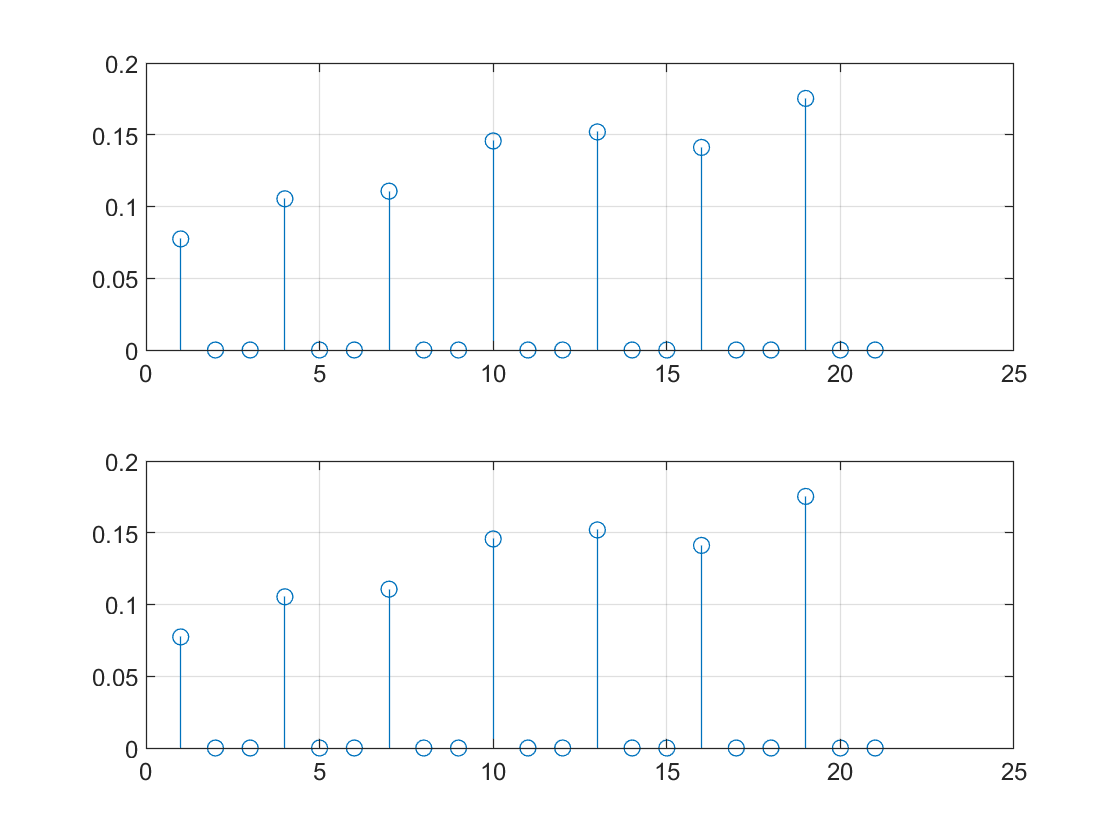

%do Upsampling
I=3;
p_Up=zeros(1,I*length(p));
counter=1;
for ind=1:length(p)
        p_Up(counter)=p(ind);
        counter=counter+I;
        p_Up(1:20);
end
%validity check 
p_Up_ctrl=upsample(p,I);
figure;
subplot(2,1,1)
stem(p_Up_ctrl(250000:250020))
grid on;
subplot(2,1,2)
stem(p_Up(250000:250020))
grid on;

#### Let's check out the spectrum :D

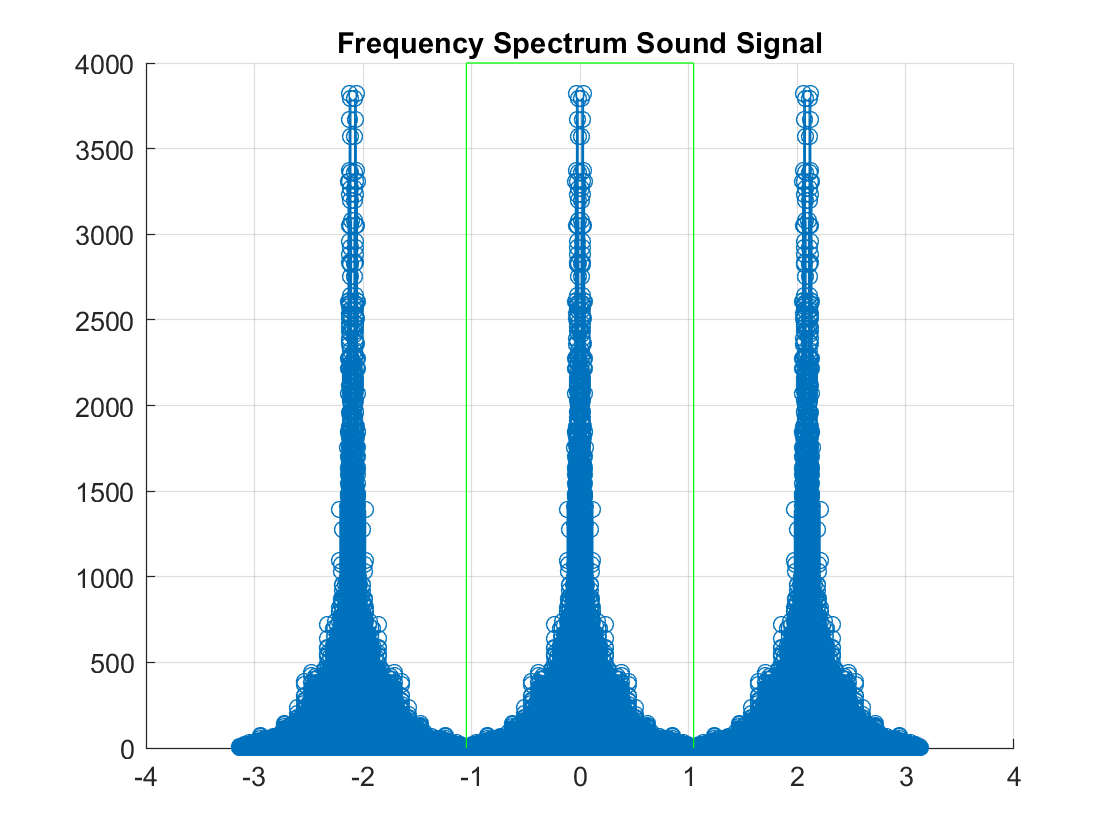

interval=[-pi:(2*pi)/(length(p_Up)):pi-(2*pi)/length(p_Up)];
figure;
hold on;
stem(interval,fftshift(abs(fft(p_Up))))
line([-pi/I pi/I],[4000 4000],'Color','green')
line([-pi/I -pi/I],[4000 0],'Color','green')
line([pi/I pi/I],[4000 0],'Color','green')
hold off;
% axis([-4 4 0 4000])
grid on;
title('Frequency Spectrum Sound Signal')

The Compressino of the Spectrum is very well visable!

let's listen to it :D

if false
%old
sound(p,44100);
% new
% sound(p_Up,44100*(I));%why doesn't this work?
sound(p_Up,44100*I)
end